# Using plotBrain.m

## Prelims

- If not already installed, please install **plotSurfaceROIBoundary** (originally written by Stuart Oldham) from [here](https://github.com/magnesium2400/plotSurfaceROIBoundary), [here](https://github.com/StuartJO/plotSurfaceROIBoundary), or [here](https://github.com/StuartJO/BrainSurfaceAnimation)[](https://github.com/StuartJO/BrainSurfaceAnimation)

- Please load data containing surface information (vertices and faces) and parcellations (e.g. from the DATA or examples folders)

if ~exist('lh_verts', 'var'); try lh_verts = lh_verts_midthickness; catch; end; end

## Plotting One Brain Surface

### Introduction

The simplest way to using plotBrain.m requires: 

- Vertices and faces of the surface to be plotted (either in a struct, or in two separate variables)

- A parcellation

-     This can be replaced with a column of 1's and 0's to denote vertices to be included or excluded, without specifying ROI boundaries

- Data to be plotted - at either vertex resolution or parcel resolution

Note that parcels with the label 0 will be colored grey (e.g. the medial wall).

A few examples are as follows:

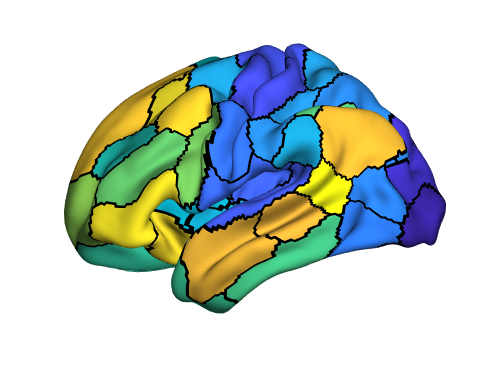

% Parcelled data, plotted in each parcel
% Check the size and shape of each input
figure; plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, (1:50).');

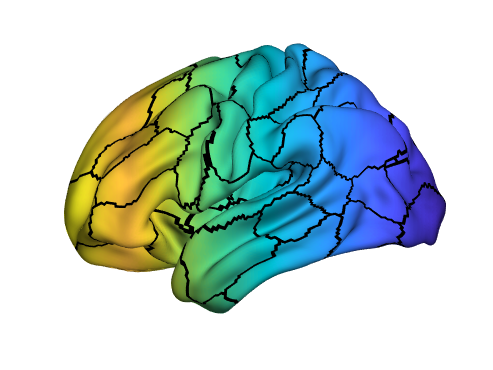


% Unparcellated data (i.e. dense vertex-level data), plotted with ROI boundaries
figure; plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, lh_verts(:,2));

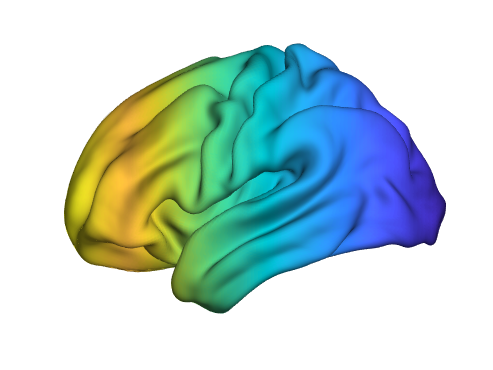


% Unparcellated data (i.e. dense vertex-level data), plotted without ROI boundaries
figure; plotBrain(lh_verts, lh_faces, logical(Scha17_parcs.lh_scha100), lh_verts(:,2));

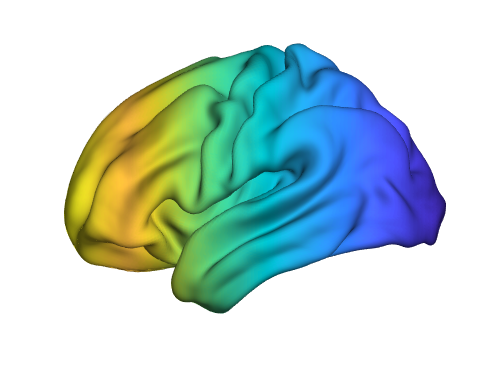


% Display data in the medial wall too
figure; plotBrain(lh_verts, lh_faces, ones(size(lh_verts, 1), 1), lh_verts(:,2));


% You can also input a struct instead of two matrices
brainSurface = struct('vertices', lh_verts, 'faces', lh_faces);
figure; plotBrain(brainSurface, ones(size(lh_verts, 1), 1), lh_verts(:,2));

When used in this way, plotBrain is a wrapper for plotSurfaceROIBoundary. Have a look at the examples and documentation for more uses of this function, including how to plot data for only certain ROIs. 

### More Options (using Name-Value Arguments)

plotBrain also contains name-value inputs that aid in modifying the appearance of the figure. Some examples are below:

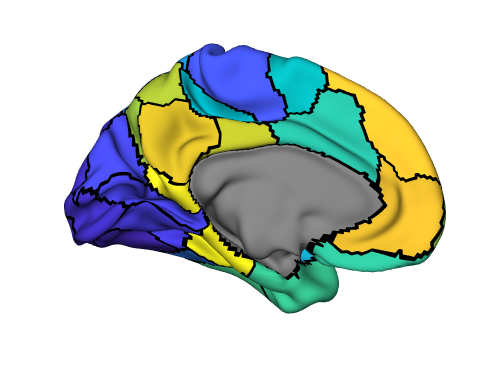

% Change the view to left medial ('lm')
figure; plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, (1:50).' - 25, 'view', 'lm');

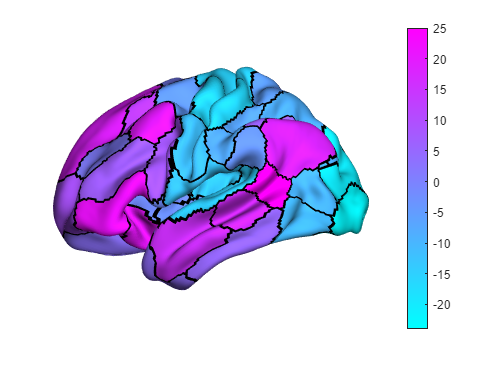


% Change the colormap
% Note that diverging/dynamic colormaps must be specified as function handles
figure; plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, (1:50).' - 25, 'colormap', cool); colorbar;

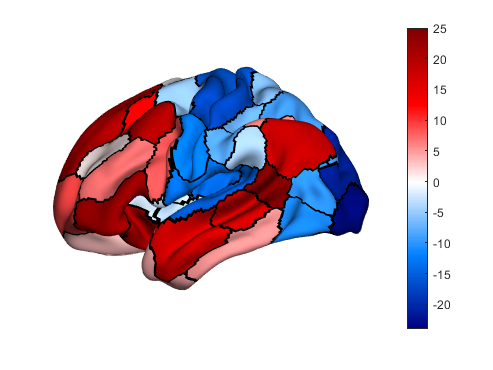

figure; plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, (1:50).' - 25, 'colormap', @bluewhitered); colorbar;

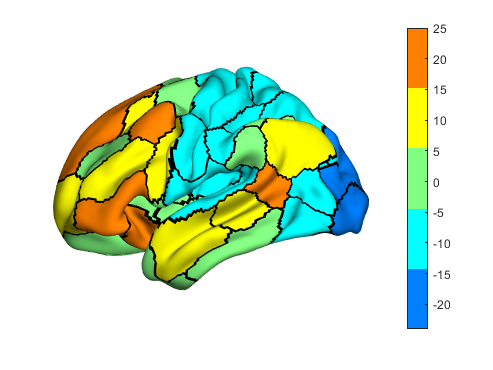

figure; plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, (1:50).' - 25, 'colormap', jet(5)); colorbar;

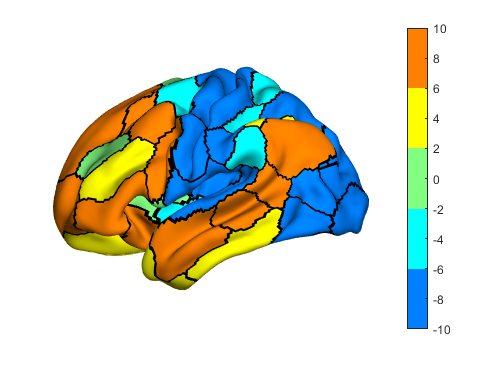


% Truncate the colormap limits - compare with above map
figure; plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, (1:50).' - 25, ...
    'colormap', jet(5), 'clim', [-10 10]); colorbar;

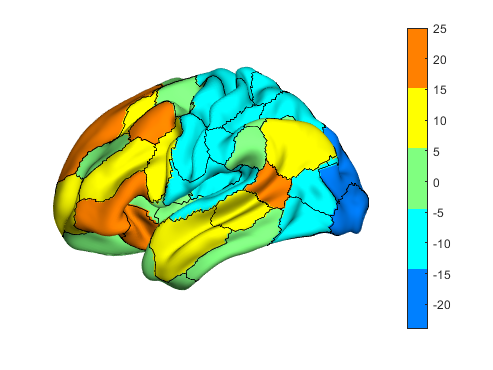


% Pass arguments to plotSurfaceROIBoundary
figure; plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, (1:50).' - 25, ...
    'plotSurfaceROIBoundaryOptions', {'midpoint', jet(5), 1} ); colorbar;

## Plotting Multiple Brain Maps

Out of the box, plotBrain also includes support for plotting more than one brain at a time (using `tiledlayout`). 

### Changing only the data map

You can plot more than one brain map at a time by changing your data input from a column vector to a matrix:

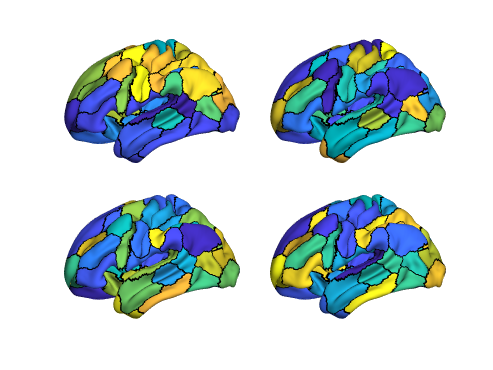

figure; plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, rand(50, 4));

### Changing only the parcellation

You can plot more than one parcellation at a time by changing the `rois` input (with data at the vertex level):

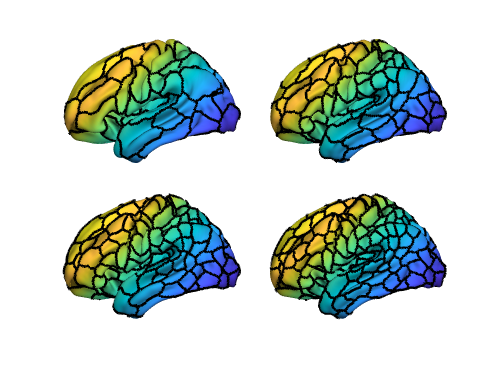

figure; plotBrain(lh_verts, lh_faces, ...
    [Scha17_parcs.lh_scha100, Scha17_parcs.lh_scha200, Scha17_parcs.lh_scha300, Scha17_parcs.lh_scha400], ...
    lh_verts(:,2)+lh_verts(:,3), 'plotSurface', {'midpoint', parula(100), 2});

### Changing only the view

You can change the view using the `'view'` Name-Value argument: the input should be a cell array consisting of either camera angles, or the keyphrases `'ll'/'lm'/'rl'/'rm' `(left/right lateral/medial), or a combination. 

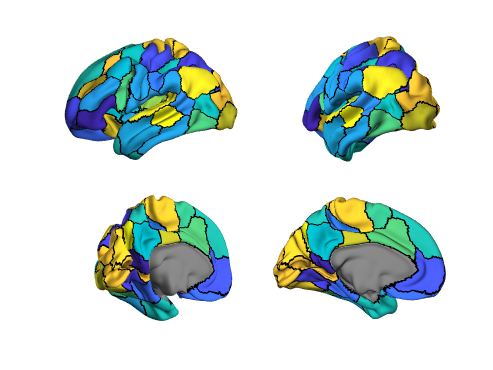

figure; plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, rand(50, 1), ...
    'view', {'ll', [-45 0], [45 0], 'lm'});

### Changing the data map and the parcellation

If there are multiple parcellations and data maps provided, these will be simultaneously varied. Note that if you are providing multiple data maps at different parcellation resolutions, this will have to be as a cell arrray.

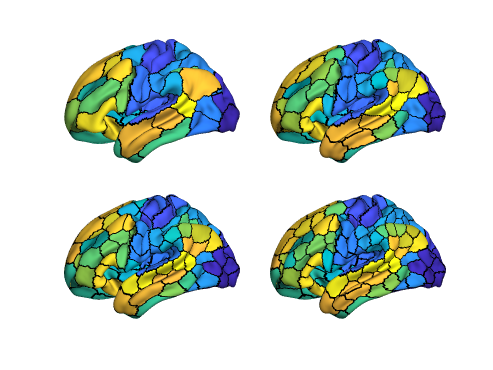

figure; plotBrain(lh_verts, lh_faces, ...
    {Scha17_parcs.lh_scha100, Scha17_parcs.lh_scha200, Scha17_parcs.lh_scha300, Scha17_parcs.lh_scha400}, ...
    {(1:50).', (1:100).', (1:150).', (1:200).'});

### Changing the shape of the grid

Grids are constructed using `tiledlayout`. The default input when `tiledlayout` is called is the argument `'flow'`. However, this can be changed using the name-value argument `'tiledlayoutOptions' `in plotBrain:

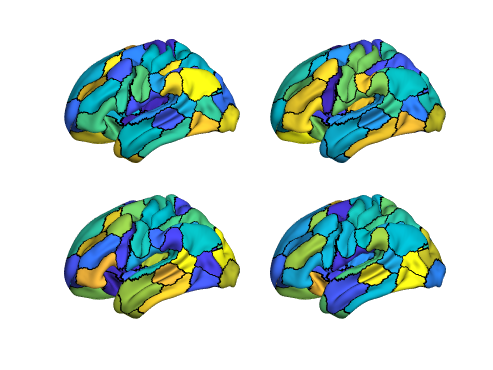

% Compare the two figures:
figure; plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, rand(50, 4));

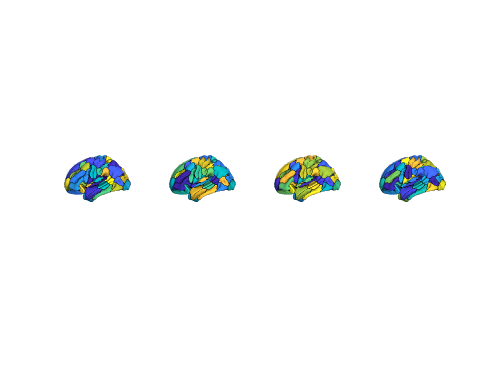

figure; plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, rand(50, 4), 'tiledlayoutOptions', {1, 4});

The tiledlayout object can also be accessed (as an output argument) and modified e.g. to add titles.

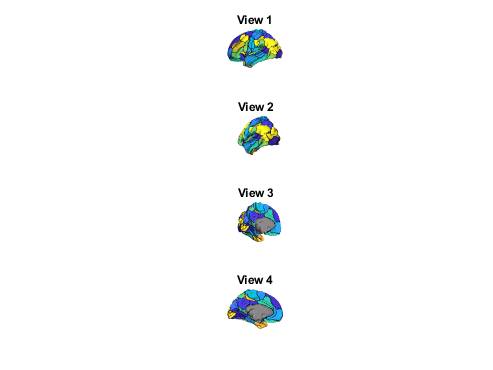

figure; [~,~,tl] = plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, rand(50, 1), ...
    'view', {'ll', [-45 0], [45 0], 'lm'}, 'tiledlayoutOptions', {4, 1, 'TileSpacing', 'loose'});
for ii = 1:4
    title(nexttile(tl, ii), sprintf("View %d", ii));
end

## Plotting Two Hemispheres

To plot two hemispheres, input the verts, faces, rois, and data for each hemisphere in two seperate cell arrays: 

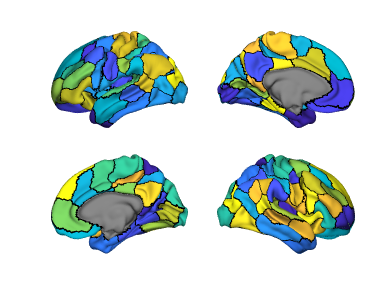

figure; 
plotBrain('lh', {lh_verts, lh_faces, Scha7_parcs.lh_scha100, rand(50,1)}, ...
    'rh', {rh_verts, rh_faces, Scha7_parcs.rh_scha100, rand(50,1)});

By default, this plots in the order ll-lm-rm-rl. This can be changed easily: 

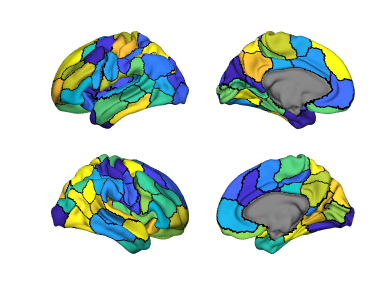

figure; 
plotBrain('lh', {lh_verts, lh_faces, Scha7_parcs.lh_scha100, rand(50,1)}, ...
    'rh', {rh_verts, rh_faces, Scha7_parcs.rh_scha100, rand(50,1)}, ...
    'viewOrder', {'ll', 'lm', 'rl', 'rm'});

## Plotting Multiple Data Maps and Views

If you supply multiple maps/parcellations and multiple input to the `'view'` argument, this will automatically produce a grid of brains (using `tiledlayout`) with each combination of map and view plotted.

By default, datasets will change as you move down columns, and views will change as you move across rows 

This can be changed by using using the name-value argument `'tiledlayoutOptions'` and the suboption `'TileIndexing'`.

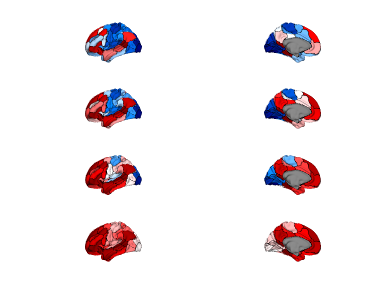

% 4 datasets, 2 views
figure; plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, (1:50).'+(-37.5:12.5:0), 'colormap', @bluewhitered, 'view', {[-90 0], [90 0]}, 'tiledlayoutOptions', {4, 2});

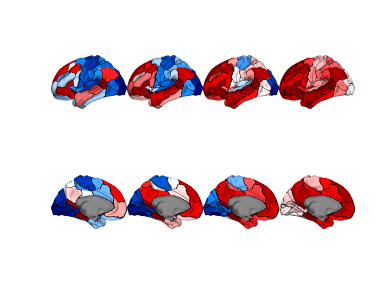

figure; plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, (1:50).'+(-37.5:12.5:0), 'colormap', @bluewhitered, 'view', {[-90 0], [90 0]}, 'tiledlayoutOptions', {2, 4, 'TileSpacing', 'none', 'TileIndexing', 'columnmajor'});

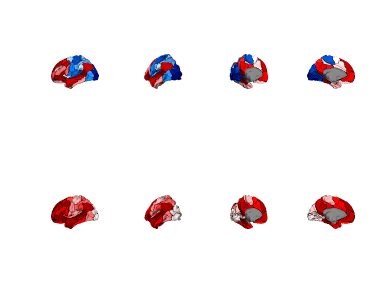


% 2 datasets, 4 views
figure; plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, (1:50).'+(-25:25:0), 'colormap', @bluewhitered, 'view', {[-90 0], [-45 0], [45 0], [90 0]}, 'tiledlayoutOptions', {2, 4});

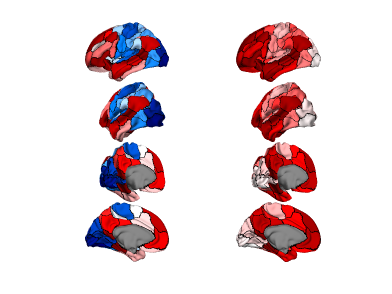

figure; plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, (1:50).'+(-25:25:0), 'colormap', @bluewhitered, 'view', {[-90 0], [-45 0], [45 0], [90 0]}, 'tiledlayoutOptions', {4, 2, 'TileSpacing', 'none', 'TileIndexing', 'columnmajor'});

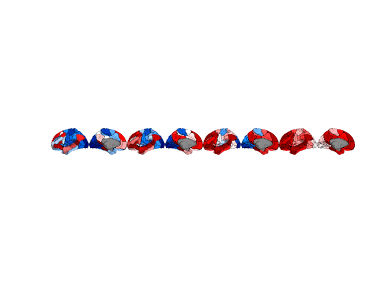


% Plot all maps in one row
figure; plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, (1:50).'+(-37.5:12.5:0), 'colormap', @bluewhitered, 'view', {[-90 0], [90 0]}, 'tiledlayoutOptions', {1, 8, 'TileSpacing', 'none'});

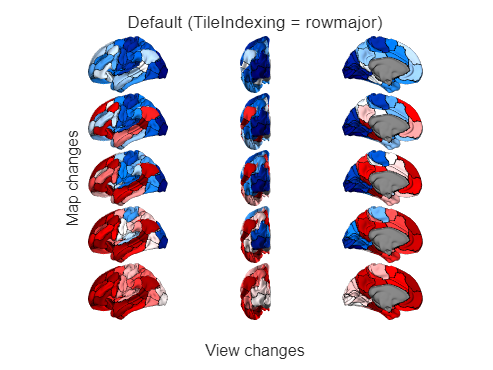

% More examples of column major indexing
% 5 datasets, 3 views
figure; [~,~,tl]=plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, (1:50).'+(-50:12.5:0), 'colormap', @bluewhitered, ...
    'view', {[-90 0], [0 0], [90 0]}, 'tiledlayoutOptions', {5, 3, 'TileSpacing', 'none',});
title(tl, 'Default (TileIndexing = rowmajor)');
xlabel(tl, 'View changes');
ylabel(tl, 'Map changes');

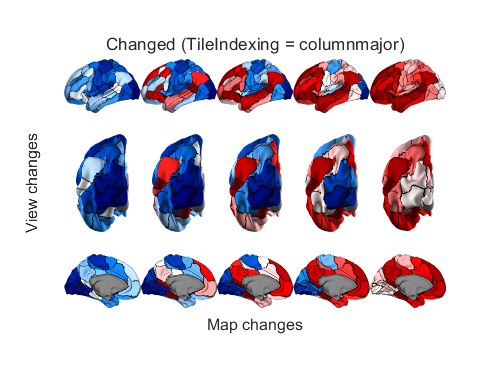


figure; [~,~,tl]=plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, (1:50).'+(-50:12.5:0), 'colormap', @bluewhitered, ...
    'view', {[-90 0], [0 0], [90 0]}, 'tiledlayoutOptions', {3, 5, 'TileSpacing', 'none', 'TileIndexing', 'columnmajor'});
title(tl, 'Changed (TileIndexing = columnmajor)');
xlabel(tl, 'Map changes');
ylabel(tl, 'View changes');

### Groupings

If using the syntax above, each map/view will be plotted on its own tile in the `tiledlayout` object.

However, you can also choose to group each map or each view together. This is useful for adding titles and colorbars to the figures. 

Instead of generating `nData * nViews` tiles (which is the default), when the `'groupBy'`argument is set to` 'data', nData` tiles are generated. Each of these is it itself a `tiledlayout`, with `nView` tiles in it. 

These subtiles can also be accessed as an output argument of plotBrain.

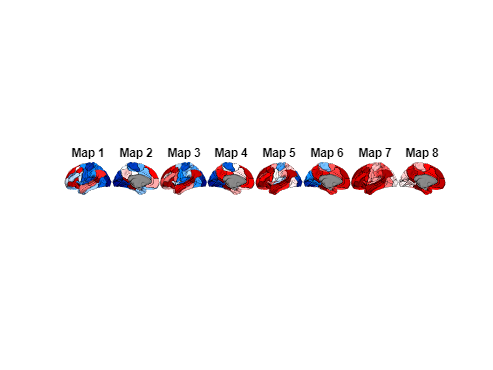

% Compare the following examples: 
% Plot all maps in one row
figure; [~,~,tl] = plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, (1:50).'+(-37.5:12.5:0), 'colormap', @bluewhitered, ...
    'view', {[-90 0], [90 0]}, 'tiledlayoutOptions', {1, 8, 'TileSpacing', 'none'});
for ii = 1:8; title(nexttile(tl, ii), sprintf("Map %d", ii)); end

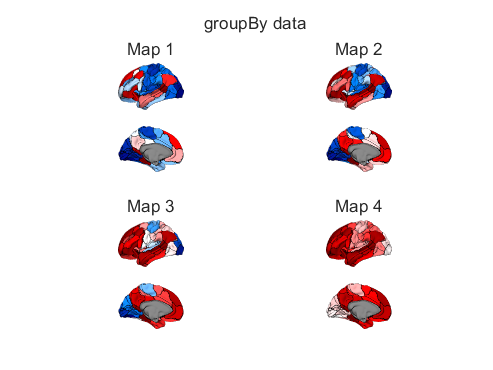


% Use groupBy data
figure; [~,~,tl,tl2] = plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, (1:50).'+(-37.5:12.5:0), 'colormap', @bluewhitered, ...
    'view', {[-90 0], [90 0]}, 'tiledlayoutOptions', {'flow', 'TileSpacing', 'compact'}, 'groupBy', 'data', 'titles', {'Map 1', 'Map 2', 'Map 3', 'Map 4'}); %#ok<*ASGLU> 
title(tl, 'groupBy data');

% Try popping out this figure and adjusting the size

The other alternative is `'groupBy', 'view'`, if desired.

## Colorschemes and Colorbars

You can add a colorbar to each group by using the `'colorbarOn'` argument. 

You can also set all maps to use the same color limits using `'colorscheme', 'global'`.

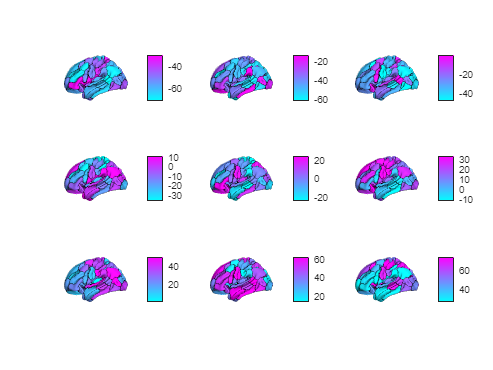

%%% regular colormaps
% each map plotted on its own colorspace and its own colorbar 
figure; plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, 50*rand(50, 9)+(-75:12.5:25), 'colormap', cool(100), 'colorbarOn', true);

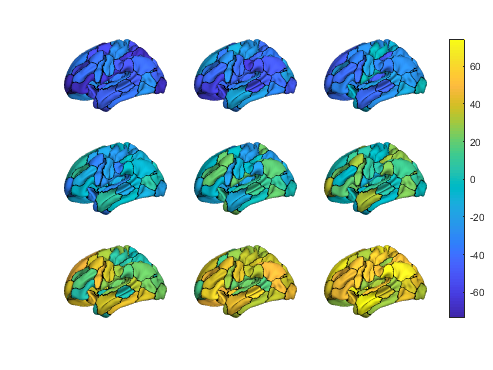

% each map plotted in a global colorscheme, with one global colorbar
figure; plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, 50*rand(50, 9)+(-75:12.5:25), 'colorscheme', 'global'); c = colorbar; c.Layout.Tile = 'east'; 

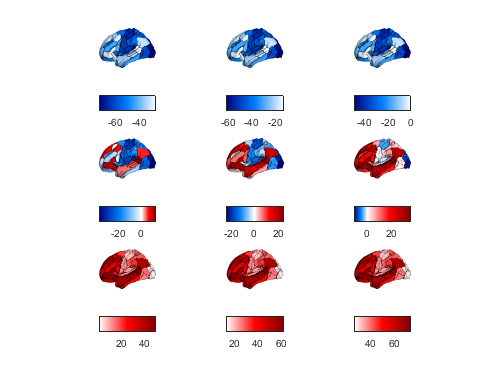


%% diverging colormaps specified as function handle
figure; plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, (1:50).'+(-75:12.5:25), 'colormap', @(x) bluewhitered(x), 'colorbarOn', true, 'colorbarOptions', {'Location', 'southoutside'});

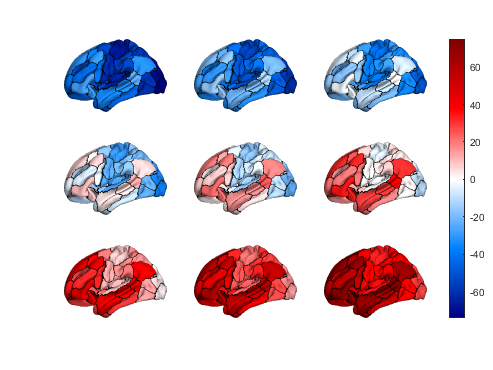

figure; plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, (1:50).'+(-75:12.5:25), 'colormap', @bluewhitered, 'colorscheme', 'global'); c = colorbar; c.Layout.Tile = 'east';

These can also be combined with the `'groupBy'` syntax:

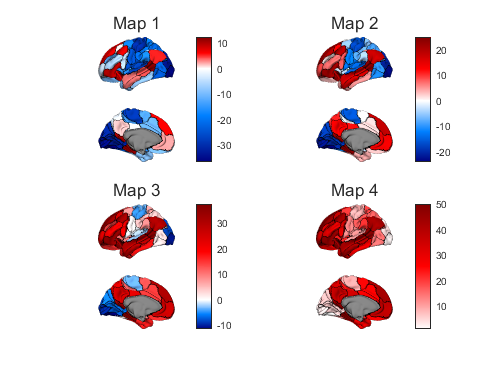

figure; [~,~,tl,tl2] = plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, (1:50).'+(-37.5:12.5:0), 'colormap', @bluewhitered, ...
    'view', {[-90 0], [90 0]}, 'groupBy', 'data', 'titles', {'Map 1', 'Map 2', 'Map 3', 'Map 4'}, 'colorbarOn', true);

## Titles

You can use the Name-Value argument `'titles'` to input a cell array of titles to be used for each plot or subplot:

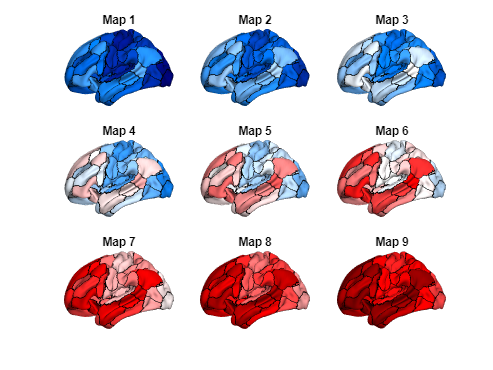

% For each map
figure; plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, (1:50).'+(-75:12.5:25), ...
    'colormap', @bluewhitered, 'colorscheme', 'global', 'view', 'll', ...
    'titles', arrayfun(@(x) sprintf('Map %d', x), 1:9, 'UniformOutput', false));


% An example when combined with groupBy
figure; [~,~,tl,tl2] = plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, (1:50).'+(-37.5:12.5:0), 'colormap', @bluewhitered, ...
    'view', {[-90 0], [90 0]}, 'groupBy', 'data', 'titles', {'Map 1', 'Map 2', 'Map 3', 'Map 4'}, 'colorbarOn', true);

## Combining into Larger Figures

You can embed `plotBrain` figures into larger figures by using the `'parent'` Name-Value argument. See `tiledlayout` for more information regarding arrangements in larger figures. 

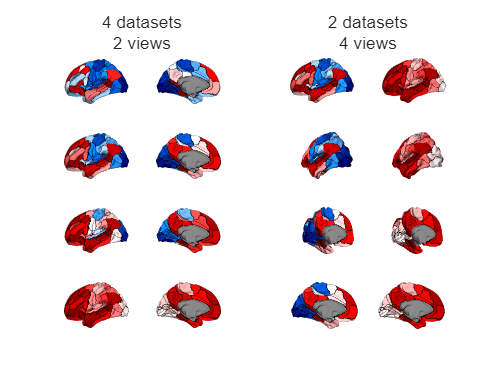

figure; 
tl = tiledlayout(1,2);

[~,~,temp] = plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, (1:50).'+(-37.5:12.5:0), 'parent', tl, 'colormap', @bluewhitered, 'view', {[-90 0], [90 0]}, 'groupBy', 'data', 'tiledlayoutOptions', {4, 1});
temp.Layout.Tile = 1;
title(temp, {'4 datasets', '2 views'});

[~,~,temp] = plotBrain(lh_verts, lh_faces, Scha17_parcs.lh_scha100, (1:50).'+(-25:25:0), 'parent', tl, 'colormap', @bluewhitered, 'view', {[-90 0], [-45 0], [45 0], [90 0]}, 'groupBy', 'view', 'tiledlayoutOptions', {4, 1});
temp.Layout.Tile = 2;
title(temp, {'2 datasets', '4 views'});